%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This script provides a demo of the clustering algorithm using a generic
% minimax path-cost function.
% Author: Pizzagalli D.U.
% Date: 2019-01-30
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;
clear all;
clc;

## SETTINGS

PATH_DATASETS = '..\dataset\mri\image_5\'; % Path to datasets
FN           = 'image_5_fg.csv';    % Dataset name.
DP_METHOD    = 'manual';        % Method to select density peaks: 'manual', 'fixed', 'topmost', 'otsu_topmost'
DP_MIN_RHO   = 10;      % Used with DP_METHOD = 'fixed'
DP_MIN_DELTA = 20;      % Used with DP_METHOD = 'fixed'
TH_PRUNING   = 10;    % Prunes edges whose cost is higher. 0 no pruning.

## DEPENDENCIES

addpath '.\utils';  %Utilities
addpath '.\libs\colorbrewer\';  %Visually different colors
addpath '.\libs\dpclustering\'; %CDP implementation
%Licenses to 3rd parties code is added in LICENSE.txt in each folder.

## INITIALIZATION

data = readmatrix([PATH_DATASETS, FN])

data =         2374          13          85           6
        2375          13          86          10
        2376          13          87          16
        2378          13          89          53
        2379          13          90          10
        2380          13          91          45
        2381          13          92         102
        2382          13          93         102
        2383          13          94         102
        2384          13          95         102


%points = dlmread([PATH_DATASETS,FN]); %RAW points
%points_idx = randperm(size(points,1));
%points = points(points_idx, :);
%ptsC_ref = dlmread([PATH_DATASETS,FN(1:end-3),'gs.txt'], '\t', 0, 1); %GT

points = data(:, 2:4)

points =     13    85     6
    13    86    10
    13    87    16
    13    89    53
    13    90    10
    13    91    45
    13    92   102
    13    93   102
    13    94   102
    13    95   102


## Uncomment to normalize variables

for dd = 1:size(points, 2) 

    points(:,dd) = points(:,dd) - min(points(:,dd)); 

    if(max(abs(points(:,dd))) > 0) 

        points(:,dd) = points(:,dd) ./ max(abs(points(:,dd))); 

    end 

end

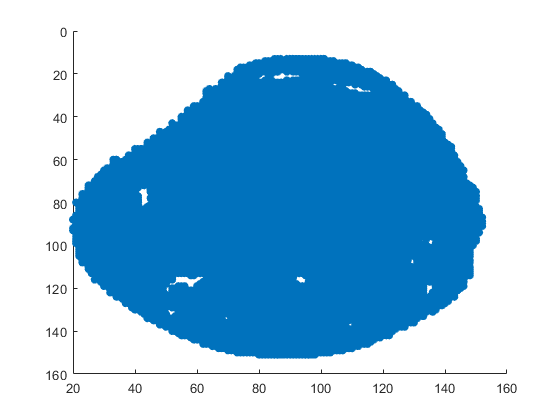

figure;
scatter(points(:,1), points(:,2), 'filled')
view([90 90])

## Randomize the order of the points

points_idx = randperm(size(points,1));

points = points(points_idx, :);

%ptsC_ref = ptsC_ref(points_idx, :);

dp1 = [67 91];
dp2 = [89 29];
%dp3 = [20 58];
dp4 = [128 97];
input_DP = [dp1; dp2; dp4]

input_DP =     67    91
    89    29
   128    97


[~,idx]= ismember(input_DP, points(:,1:2),"rows");
idx

idx =         3951
        6581
       11089


points = normalize(points)

points =    -2.1596   -0.1092   -1.7698
   -2.1596   -0.0776   -1.7141
   -2.1596   -0.0461   -1.6306
   -2.1596    0.0169   -1.1155
   -2.1596    0.0484   -1.7141
   -2.1596    0.0799   -1.2269
   -2.1596    0.1114   -0.4334
   -2.1596    0.1430   -0.4334
   -2.1596    0.1745   -0.4334
   -2.1596    0.2060   -0.4334


## DP

Manually select a proper rectangle to determine all the cluster centres (use Decision Graph)!
The only points of relatively high *rho* and high  *delta* are the cluster centers!


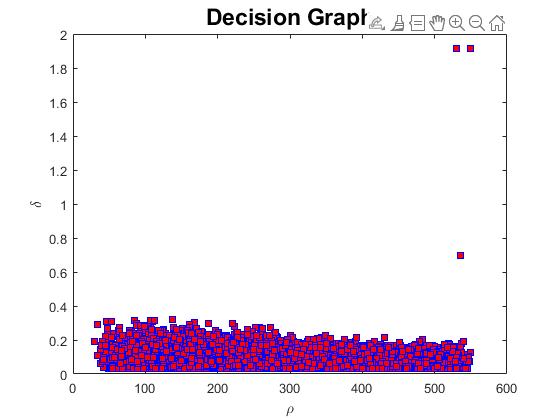

[centers_DP, ptsC_DP] = dpeuclidean(points, DP_MIN_RHO, DP_MIN_DELTA, DP_METHOD);

cdp = centers_DP

cdp =         4284
        4314
       10262


centers_DP = idx

centers_DP =         3951
        6581
       11089


## DP with Shortest Path

%requires as input points, the id of the points to be used as seeds and the
%eventual pruning.
[centers_DI, ptsC_DI, path_DI] = dpshortest_minimax(points, centers_DP, TH_PRUNING);

ptsC_DI

ptsC_DI =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


## Evaluation

[TP_DP,FP_DP,TN_DP,FN_DP,precision_DP,recall_DP,F1_DP,J_DP] = evaluateClusteringResults(ptsC_DP, ptsC_ref);

[TP_DI,FP_DI,TN_DI,FN_DI,precision_DI,recall_DI,F1_DI,J_DI] = evaluateClusteringResults(ptsC_DI, ptsC_ref);

disp(['F1 (ClusterDP) on ', FN, ' = ', num2str(F1_DP)]);

disp(['F1 (ClusterDP with Shortest Path) on ', FN, ' = ', num2str(F1_DI)]);

## Visualization

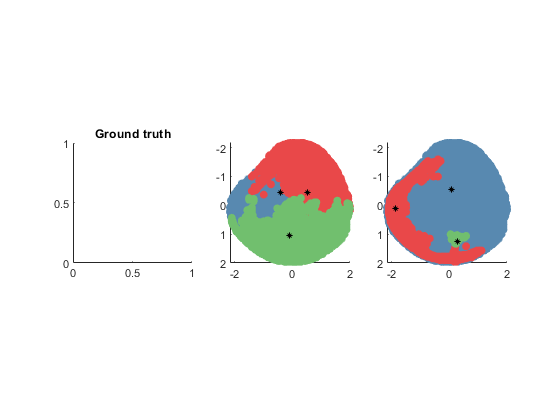

fn_str = strrep(FN, '_', '\_');
figure;
subplot(131);
%plot_clustered_points(points, ptsC_ref, false);
title('Ground truth');
axis equal; axis square;

subplot(132);
plot_clustered_points(points(:, 1:2), ptsC_DP, false);
hold on;
plot(points(cdp, 1), points(cdp, 2), '*', 'MarkerEdgeColor', [0,0,0], 'MarkerSize', 4);
axis equal; axis square;
view([90 90])
%title(['ClusterDP F1=',num2str(F1_DP),' J=',num2str(J_DP)]);

subplot(133);
plot_clustered_points(points(:, 1:2), ptsC_DI, false);
view([90 90])
%title(['DIJ minimax F1=',num2str(F1_DI),' J=',num2str(J_DI)]);
hold on;
plot(points(centers_DP, 1), points(centers_DI, 2), '*', 'MarkerEdgeColor', [0,0,0],  'MarkerSize', 4);
axis equal; axis square;

labeled_data = array2table([data ptsC_DI],...
    'VariableNames',{'Index','X-coordinate','Y-coordinate','Intensity', 'Labels'})

labeled_data = 12562×5 table
    Index    X-coordinate    Y-coordinate    Intensity    Labels
    _____    ____________    ____________    _________    ______

    2374          13              85              6         1   
    2375          13              86             10         1   
    2376          13              87             16         1   
    2378          13              89             53         1   
    2379          13              90             10         1   
    2380          13              91             45         1   
    2381          13              92            102         1   
    2382          13              93            102         1   
    2383          13              94            102         1   
    2384          13              95            102         1   
    2385          13

output_file = 'image_5_fg_labeled.csv'

output_file = 'image_5_fg_labeled.csv'

writetable(labeled_data, [PATH_DATASETS, output_file])